clc,clear,close all

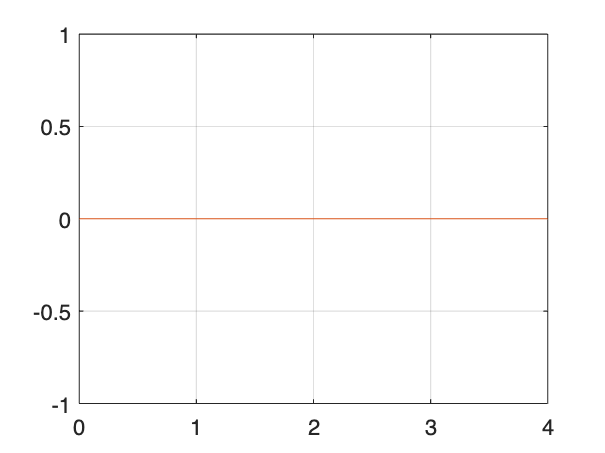

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [1, 1];
kr = [1/10,1/5];

% link dimension
lx=[0.20 0.20]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m

%material properties
density=2660; % [kg/m3] AW 5083 alloy
%rho=(density*1000)/100^3; %[g/cm3]
rho = density; 

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end
%u = [y(:,1),-pi/2*ones(length(t),1)];% y(:,1)]; % control both the motors in the same way

%step

u=[zeros(length(t),1), zeros(length(t),1)];

figure
plot(t, u);
grid on;


methods=dynlib;
syms("q1", "q2", "dq1", "dq2");
q = [q1, q2];
dq = [dq1, dq2];
[Bq, Cq, gq] = methods.dyn(lx, ly, lz, rho, mm, Im, kr)

$$Bq = \left(\begin{array}{cc} \frac{3\,\cos\left(\bar{q_{1}}\right)\,\cos\left(q_{1}\right)}{12500}+\frac{3\,\sin\left(\bar{q_{1}}\right)\,\sin\left(q_{1}\right)}{12500}+\frac{3703165756564404643089561612350070838268760467}{141429858751515048876965071213828662886400000000} & \frac{5824613637837130376244037680557500781564760467}{282859717503030097753930142427657325772800000000}-\frac{332041393326771933\,\sin\left(q_{1}\right)}{461168601842738790400000}-\frac{3\,\cos\left(q_{1}\right)}{1250000}\\ \frac{5824613637837130376244037680557500781564760467}{282859717503030097753930142427657325772800000000}-\frac{332041393326771933\,\sin\left(\bar{q_{1}}\right)}{461168601842738790400000}-\frac{3\,\cos\left(\bar{q_{1}}\right)}{1250000} & \left(\frac{399\,\sin\left(\bar{q_{1}}\right)}{12500}-\frac{332041393326771933}{92233720368547758080000}\right)\,\left(\frac{\sin\left(q_{1}\right)}{5}-\frac{832183943174867}{36893488147419103232}\right)+\left(\frac{\cos\left(q_{1}\right)}{5}-\frac{1}{13300}\right)\,\left(\frac{399\,\cos\left(\bar{q_{1}}\right)}{12500}-\frac{3}{250000}\right)+\frac{4748164254456728029}{230584300921369395200} \end{array}\right)$$

$$Cq = \begin{array}{l} \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{1}\,\left(\frac{332041393326771933\,\cos\left(\bar{q_{1}}\right)}{922337203685477580800000}-\frac{3\,\sin\left(\bar{q_{1}}\right)}{2500000}+\frac{332041393326771933\,\cos\left(q_{1}\right)}{922337203685477580800000}-\frac{3\,\sin\left(q_{1}\right)}{2500000}\right)\\ -{\mathrm{dq}}_{2}\,\sigma_{1} & {\mathrm{dq}}_{1}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{399\,\cos\left(\bar{q_{1}}\right)\,\left(\frac{\sin\left(q_{1}\right)}{5}-\frac{832183943174867}{36893488147419103232}\right)}{25000}-\frac{399\,\sin\left(\bar{q_{1}}\right)\,\left(\frac{\cos\left(q_{1}\right)}{5}-\frac{1}{13300}\right)}{25000}-\frac{\sin\left(q_{1}\right)\,\left(\frac{399\,\cos\left(\bar{q_{1}}\right)}{12500}-\frac{3}{250000}\right)}{10}+\frac{\cos\left(q_{1}\right)\,\left(\frac{399\,\sin\left(\bar{q_{1}}\right)}{12500}-\frac{332041393326771933}{92233720368547758080000}\right)}{10} \end{array}$$

$$gq = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

F = [0 0; 0 0]; % TEMP

% Initial Values

qt = [-pi/2;-pi/2];
dqt = [0;0];
ddqt = [0;0];

%{
%controller variables
Kp = diag([1/80 1/80 0 1/80 0 1/80]);
Kd = diag([1/80 1/80 0 1/80 0 1/80]);
%}

kc=4*(l(1))

var=[ 2 1.2 0 1.8 0 1.6 ];
Kp= diag([var.^2./2]);
Kd=diag(var);



% Simulation
actual_q = [];

wb = waitbar(0, "<Simulating...>");
for i = 1:length(t)
    B = double(subs(Bq, q, qt'));
    C = double(subs(Cq, [q, dq], [qt', dqt']));
    g = double(subs(gq, q, qt'));
    ut = u(i,:);
    out=sim("SimulationSS", "FixedStep", num2str(t_step));
    % is the following code correct?
    qt = out.q(end, :)'; % get only the last values of the simulation
    dqt = out.dq(end, :)';
    ddqt = out.ddq(end, :)';
    actual_q = [actual_q; out.q(end,:)];
    waitbar(i/length(t));
end
close(wb);

figure
plot(t, u, t, actual_q);
grid on;
legend('q_1*', 'q_2*', 'q_1', 'q_2');

%{
methods = dynlib;
t_end = 4;
[A, ~] = methods.criticaltrajectory(t_end, amax);
%A = methods.polynomial([-pi/2; 0; pi/2], [0; 0], [0; amax; 0], [0, t_end/2, t_end], [0, t_end], [0, t_end/4, t_end]);
t = [0:0.01:t_end];
y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end
plot(t,y);
legend("q", "q\_dot", "q\_ddot");
%}

%{
[B, C, g] = methods.dyn(lx,ly,lz,rho, mm, Im, kr)
syms("q1","q2","dq1","dq2");
Bq=simplify(subs(B,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))
Cq=simplify(subs(C,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))
%}

%{
% starting the simulation
methods = dynlib;
Tf = 4;
step_size = 0.01;
t = [0:step_size:Tf];

syms("q1", "q2", "dq1", "dq2");
q = [q1, q2];
dq = [dq1, dq2];

q_current = [0; 0];
dq_current = [0; 0];
ddq_current = [0; 0];

[Bq, Cq, gq] = methods.dyn(lx, ly, lz, rho, mm, Im, kr);
F = [0 0; 0 0]; % TEMP

A = methods.criticaltrajectory(Tf, amax);

y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

q_actual = [];

for i = 1:length(t)
    B = double(subs(Bq, q, q_current'));
    C = double(subs(Cq, [q, dq], [q_current', dq_current']));
    g = double(subs(gq, q, q_current'));
    u = y(i, 3);
    sim("Simulation");
    q_current = out.q;
    dq_current = out.dq;
    ddq_current = out.ddq;
    q_actual = [q_actual; q_current'];
end

plot(t, q_actual, t, y(i, 1));

%}


























































